# Lagrangian Method

% Define the file path
filePath = "C:\Users\raymo\Desktop\Tremor_VA-Raymond-2024-04-27\videos\distanceDLC_resnet50_Tremor_VAApr27shuffle1_340000.csv";

% Specify options for reading the file
opts = detectImportOptions(filePath);
opts.SelectedVariableNames = [2, 3]; % Reading the second and third columns
opts.DataLines = [4, Inf];  % Start reading from row 4 to the end of the file

% Read the CSV file into a table with specified options
dataTable = readtable(filePath, opts);

% Assign columns to X and Y
wrist_x = dataTable{:,1};
wrist_y = dataTable{:,2};

% Display first few rows of X and Y to verify they are loaded correctly
disp(head(wrist_x));

   1.0e+03 *

    1.6742
    1.6735
    1.6728
    1.6732
    1.6738
    1.6746
    1.6746
    1.6752



disp(head(wrist_y));

   1.0e+03 *

    1.1586
    1.1559
    1.1554
    1.1534
    1.1527
    1.1523
    1.1505
    1.1494



## Plot positions

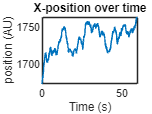

fs = 60; % sampling frequency (Hz)
t = 0:1/fs:length(wrist_x)/fs-1/fs;
figure;
plot(t,wrist_x);
title('X-position over time'); xlabel('Time (s)'); ylabel('position (AU)');

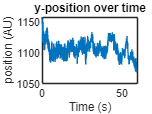


figure;
plot(t,wrist_y);
title('y-position over time'); xlabel('Time (s)'); ylabel('position (AU)');

## Kalman Filter 

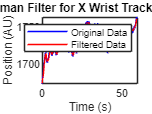

% Initialize Kalman filter parameters
A = eye(1); % State transition matrix (for almost constant position)
H = 1; % Measurement matrix (only position is measured)
Q = 0.01; % Process noise covariance (low because we assume almost constant position)
R = 1; % Measurement noise covariance (only position is measured)
xX = wrist_x(1);  % Initial state estimate for X position
xY = wrist_y(1);  % Initial state estimate for Y position
P = 0.1;  % Initial error covariance

n = length(wrist_x);  % Number of samples
filteredX = zeros(n, 1);
filteredY = zeros(n, 1);

% Kalman filtering for X data
for k = 1:n
    % Prediction
    xPred = A * xX;
    PPred = A * P * A' + Q;

    % Update
    K = PPred * H' / (H * PPred * H' + R);
    xX = xPred + K * (wrist_x(k) - H * xPred);
    P = (1 - K * H) * PPred;
    filteredX(k) = xX;
end

% Kalman filtering for Y data
for k = 1:n
    % Prediction
    xPred = A * xY;
    PPred = A * P * A' + Q;

    % Update
    K = PPred * H' / (H * PPred * H' + R);
    xY = xPred + K * (wrist_y(k) - H * xPred);
    P = (1 - K * H) * PPred;
    filteredY(k) = xY;
end

% Plot original and filtered data for X
figure;
plot(t, wrist_x, 'b', t, filteredX, 'r');
legend('Original Data', 'Filtered Data');
xlabel('Time (s)');
ylabel('Position (AU)');
title('Kalman Filter for X Wrist Tracking Data');

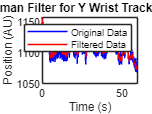


% Plot original and filtered data for Y
figure;
plot(t, wrist_y, 'b', t, filteredY, 'r');
legend('Original Data', 'Filtered Data');
xlabel('Time (s)');
ylabel('Position (AU)');
title('Kalman Filter for Y Wrist Tracking Data');

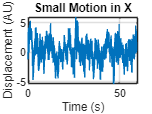


% Subtract the smooth trajectories from the original data to isolate small motions
small_motionX = wrist_x - filteredX;
small_motionY = wrist_y - filteredY;

% Plot small motion for X
figure;
plot(t, small_motionX);
title('Small Motion in X');
xlabel('Time (s)');
ylabel('Displacement (AU)');
grid on;

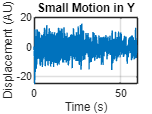


% Plot small motion for Y
figure;
plot(t, small_motionY);
title('Small Motion in Y');
xlabel('Time (s)');
ylabel('Displacement (AU)');
grid on;

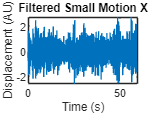


% Design 4th order Butterworth bandpass filter
low_cut = 2;  % Lower cutoff frequency (Hz)
high_cut = 14;  % Higher cutoff frequency (Hz)
[b, a] = butter(2, [low_cut/(fs/2) high_cut/(fs/2)], 'bandpass');

% Apply the bandpass filter to the small motion data
small_motionX = filter(b, a, small_motionX);
small_motionY = filter(b, a, small_motionY);

% Plot filtered small motion X
figure;
plot((0:length(small_motionX)-1)/fs, small_motionX);
title('Filtered Small Motion X');
xlabel('Time (s)');
ylabel('Displacement (AU)');

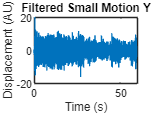


% Plot filtered small motion Y
figure;
plot((0:length(small_motionY)-1)/fs, small_motionY);
title('Filtered Small Motion Y');
xlabel('Time (s)');
ylabel('Displacement (AU)');

## Lagrangian Method

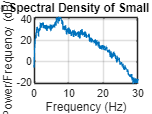

% windowed FT -> PSD
% Windowed Fourier Transform -> PSD for x-component
[sX, FX, TX] = spectrogram(small_motionX, [], [], [], fs);
psd_X = sum(abs(sX).^2, 2);

% Windowed Fourier Transform -> PSD for y-component
[sY, FY, TY] = spectrogram(small_motionY, [], [], [], fs);
psd_Y = sum(abs(sY).^2, 2);

% Plot the PSD for the X component
figure;
plot(FX, 10*log10(psd_X));
title('Power Spectral Density of Small Motion X');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;

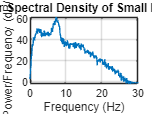


% Plot the PSD for the Y component
figure;
plot(FY, 10*log10(psd_Y));
title('Power Spectral Density of Small Motion Y');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;


% psd_L = psd_Y

psd_L = 1.0e+06 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0004
    0.0003
    0.0008


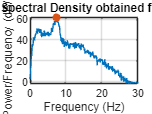

% Combine the PSDs from x and y components
psd_L = psd_X + psd_Y;

% Plot the PSD
figure;
plot(FX, 10*log10(psd_L));
title('Power Spectral Density obtained from STFT');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on
hold on

[maxVal, maxInd] = max(psd_L); % plot max value
amplitude = 10*log10(maxVal); % amplitude of dominant tremor frequency
scatter(FX(maxInd),10*log10(maxVal),'filled');

disp([num2str(FX(maxInd)), ' Hz'])

7.2656 Hz


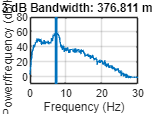


% 3-dB (half power) bandwidth 
[bandwidth, freq_lower, freq_higher, band_power] = powerbw(psd_L, FX);
figure; 
powerbw(psd_L, FX);

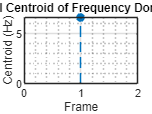


% spectral centroid
spectral_centroid = spectralCentroid(psd_L, FX);
figure;
spectralCentroid(psd_L, FX);
title("Spectral Centroid of Frequency Domain Data")

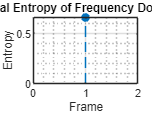


% Calculate spectral entropy
spectral_entropy = spectralEntropy(psd_L, FX);
figure;
spectralEntropy(psd_L, FX);
title("Spectral Entropy of Frequency Domain Data")


disp(['Dominant Frequency: ', num2str(FX(maxInd)), ' Hz'])

Dominant Frequency: 7.2656 Hz


disp(['Amplitude: ', num2str(amplitude), ' dB/Hz'])

Amplitude: 61.9356 dB/Hz


disp(['Bandwidth: ', num2str(bandwidth), ' Hz'])

Bandwidth: 0.37681 Hz


disp(['Lower Bound: ', num2str(freq_lower), ' Hz'])

Lower Bound: 7.0808 Hz


disp(['Upper Bound: ', num2str(freq_higher), ' Hz'])

Upper Bound: 7.4576 Hz


disp(['Percent Power Stored in Bandwidth: ', num2str(band_power), ' dB']);

Percent Power Stored in Bandwidth: 454847.9274 dB


disp(['Spectral Centroid: ', num2str(spectral_centroid), ' Hz']);

Spectral Centroid: 6.6884 Hz


disp(['Spectral Entropy: ', num2str(spectral_entropy)]);

Spectral Entropy: 0.66942
